# Taxi Deployment 

## Data Extraction and Introduction 

To get started, navigate to the Taxi Project folder, and run the script **generateTaxiPickupTable.mlx**. 

*Note it may take a while to finish. *

This will create (and save) two tables: `pickupLocations` and `taxiPickups. `A preview and description of each table is given below. 

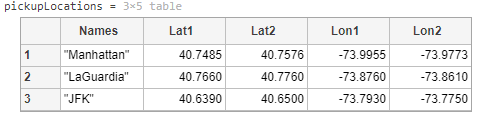

The table `pickupLocations` gives the latitude and logitude bounds for three pickup zones: 

- **Manhattan**: here meaning an area of high taxi traffic surrounding Penn Station, Grand Central Station, and the Port Authority Bus Terminal

- **LaGuardia**: meaning an area surrounding LaGuardia airport

- **JFK**: similarly meaning an area surrounding JFK airport. 

The zones are shown below for reference. 

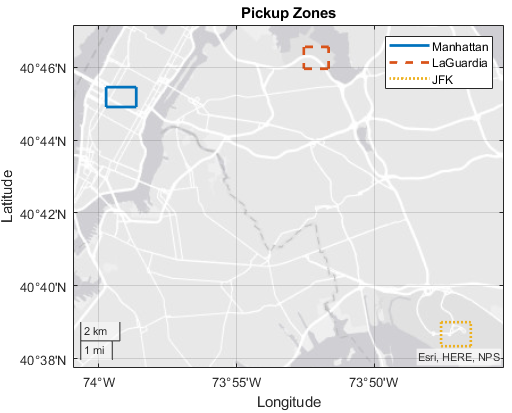

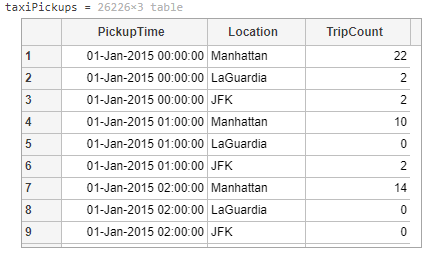

The table `taxiPickpus` represents the number of pickups in your data over one hour intervals of 2015 in the zones defined in `pickupLocations`. The start of each hour is specified in the `PickupTime` datetime variable, the zone is specified by the `Location` categorical variable, and the number of pickups is given by the `TripCount`. 

## Data Exploration and Partitioning 

The script **generateTaxiPickupTable.mlx **in the previous section saved copies of the tables to a MAT file named **taxiPickupData.mat**. To avoid having to run the script again if you continue working after clearing your workspace, the code below loads the saved data. 

% Make sure to follow the instructions in the previous section
if ~isempty(which('-all','taxiPickupData.mat'))
    load taxiPickupData.mat 
else
    error("The file taxiPickupData.mat is not found " + ...
        "on the MATLAB path. Add it to the path or run" + ...
        "  generateTaxiPickupTable.mlx to generate it.")
end

### Visualization and Analysis

Analyze the data in the `taxiPickups` table. At a minimum, provide a visualization of the distribution (histogram) of the response variable `TripCount`, as well as a box plot for `TripCount` grouped by `Location`. 

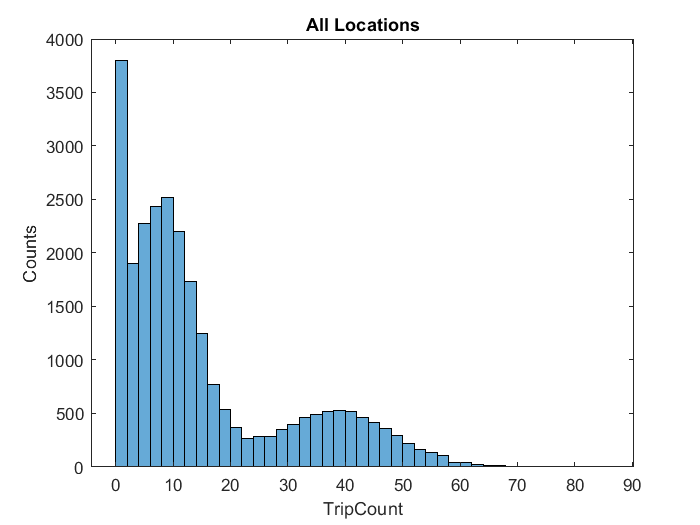

histogram(taxiPickups.TripCount)
title('All Locations');
xlabel('TripCount');
ylabel('Counts');

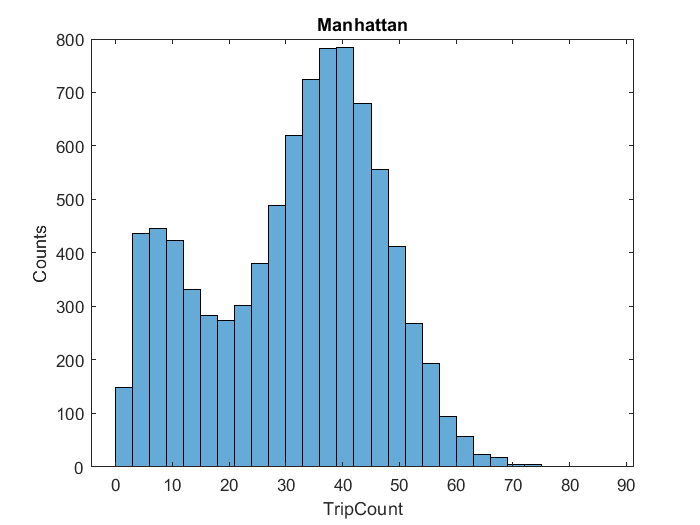

histogram(taxiPickups.TripCount(taxiPickups.Location ...
    =='Manhattan'))
title('Manhattan');
xlabel('TripCount');
ylabel('Counts');

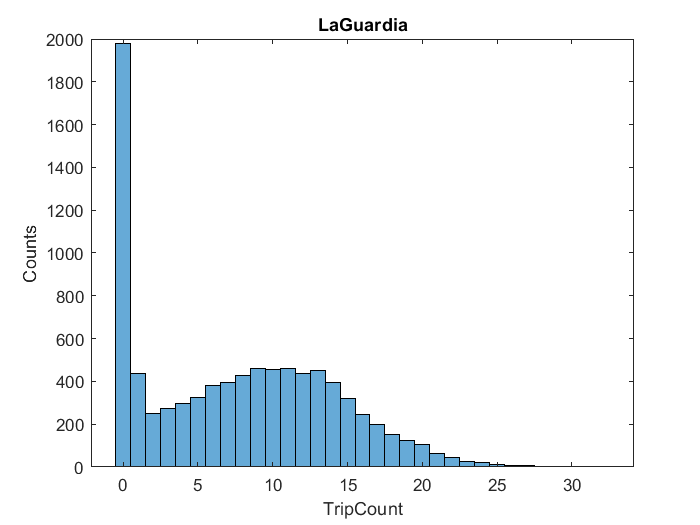

histogram(taxiPickups.TripCount(taxiPickups.Location ...
    =='LaGuardia'))
title('LaGuardia');
xlabel('TripCount');
ylabel('Counts');

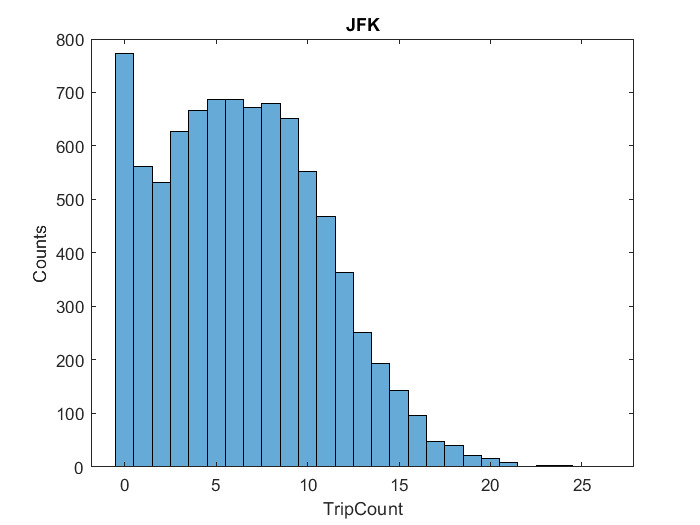

histogram(taxiPickups.TripCount(taxiPickups.Location ...
    =='JFK'))
title('JFK');
xlabel('TripCount');
ylabel('Counts');

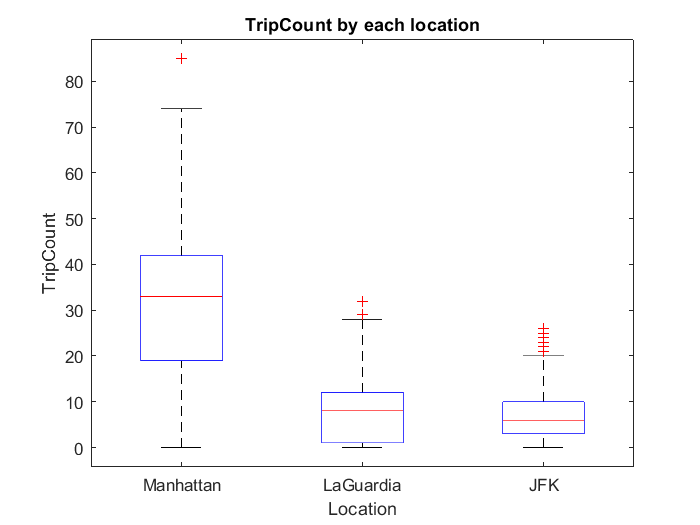

boxplot(taxiPickups.TripCount,taxiPickups.Location)
title('TripCount by each location');
xlabel('Location')
ylabel('TripCount');

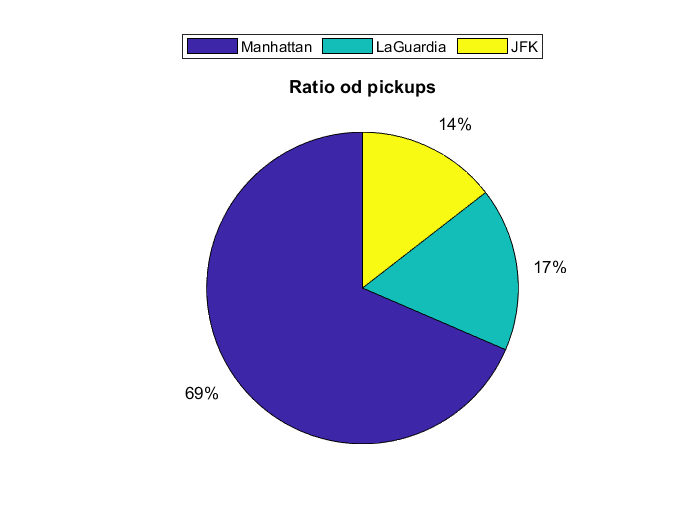

g = groupsummary(taxiPickups,"Location",'sum', ...
    'TripCount');
figure
pie(g.sum_TripCount)
title('Ratio od pickups')
legend('Manhattan','LaGuardia','JFK','Location', ...
    "northoutside","Orientation","horizontal")

After analysis of data we conclude that the manhattan location covered more trips aproximately doubled to another location.

### Separate Test Data 

Use `cvpartition` to separate 20% of the data set for testing later on, and create the training data. Ensure your results are repeatable by setting the random number generator seed to 10. Provide your code. 

rng(10); 
taxiPartitions = cvpartition(height(taxiPickups),"HoldOut",0.2);
taxiTestIdx = test(taxiPartitions); 

Subscripting into a table using one subscript (as in t(i)) or three or more subscripts (as in t(i,j,k)) is not supported. Always specify a row subscript and a variable subscript, as in t(rows,vars).

taxiPickupsTest = taxiPickups(taxiTestIdx,:);
taxiTrainIdx = training(taxiPartitions); 
taxiPickupsTrain = taxiPickups(taxiTrainIdx,:); 

## Models Training and Validation 

### Preprocessing 

As the focus of this course is machine learning, we’ve provided a function to do some feature engineering for you. Use **providedPreprocessing.mlx **to add the following features to your training/validation data set:

- `TimeOfDay` (numerical)

- `DayOfWeek` (categorical)

- `DayOfMonth` (numerical)

- `DayOfYear` (numerical) 

For example: 

taxiPickupsTrain = providedPreprocessing(taxiPickupsTrain);

### Model Training

Train models to predict `TripCount` using the processed test/validation data. **Report your validation approach and validation**$RMSE$** for your best model**. Your goal will be to get a validation$RMSE$ at or below $4.9$. Include code so that your script can reproduce your final model, including the model training. **If using the app, export the training function** and include a correct call to it in your script. Note you do not need to include the generated training function code itself in your script, just a correct call to it. For example, if you'd trained a tree model in the app and exported the training function, you could include: 

[trainedModel, validationRMSE] = trainRegressionModel(taxiPickupsTrain)

myModel = trainedModel.RegressionEnsemble

**Validation **$RMSE$: 4.6781

**Validation Method**:  Cross validation of 20 fold

## Model Testing and Evaluation 

### Testing

Preprocess the test data as needed, and use it to test your best model. Provide your code and report at least the $RMSE$ and $R^2$. You will need to achieve a test $RMSE$ at or below $4.9$ to receive full points here. 

taxiPickupsTest = providedPreprocessing(taxiPickupsTest);
ypredict = predict(trainedModel.RegressionEnsemble,taxiPickupsTest);
yActual = taxiPickupsTest.TripCount;
residual = yActual-ypredict;
RMSE = sqrt(mean(residual.^2))

test = rMetrics(yActual,ypredict);
display(test)

**Test RMSE** : 4.7003

$R^2$** :** 0.9014

### Evaluation

histogram2(yActual, ypredict,64,"DisplayStyle","tile", ...
    "EdgeColor","auto")
line([0,65],[0,65],'Color','yellow','LineStyle','-', ...
    'LineWidth',3)
xlabel("Actual Trips")
ylabel("Predicted Trips")
title("Predicted Vs Actual Plot")
cb = colorbar();
cb.Label.String = "Points";

histogram2(yActual, residual, 64, "DisplayStyle","tile")
line([0 65], [0 0], "Color", "yellow",'LineStyle','-', ...
    'LineWidth',3)
xlabel("Actual TripCount")
ylabel("Residuals")
title("Residuals Plot")
cb = colorbar();
cb.Label.String = "Points"

Discuss the results from training and testing. How well did your model generalize to new data? Include at least a plot of the residuals, and discuss your observations from the plot(s). 

As seen in the first plot the large number of points having zero trips biasing the regression model the training result having a rmse of 4.6781 and the testing rmse is slightly bigger than training. This results shows the training model is slightly overfitting.

The second residual plot shows the distribution of errors the maximum residuals shown between the range of 10 to -10 and less numbers of residual shown in maximum range of 20 to 25.From the below plot we can easily carify the distribution of residuals.

histogram(residual)
xlabel("Residuals");
ylabel("counts");
title("Residuals");

## Model Application, Results, and Analysis

### Apply Model 

As the focus of this course is machine learning, we’ve provided some skeleton code in this section. Below, we create a new table of staring features for 2016. 

*Note that you will need to use the variable names provided in comments or make your own additional edits to the code.*

taxiPickups2016 = table; 
taxiPickups2016.PickupTime = taxiPickups.PickupTime + years(1); 
taxiPickups2016.Location = taxiPickups.Location;
taxiPickups2016 = providedPreprocessing(taxiPickups2016); 
% Display only the first 8 rows of the table
head(taxiPickups2016)

Choose your favorite day in 2016 and edit the variable `myDay` below which will be used to extract that day from the table. 

myDay = datetime("2016-12-6")
 taxiPickupsMyDay = taxiPickups2016(day(taxiPickups2016.PickupTime,"dayofyear") == day(myDay,"dayofyear"),:)
 head(taxiPickupsMyDay)

Now, use your best model to predict `TripCount` on the day you've chosen and add it to the table. 

taxiPickupsMyDay.TripCount = predict(trainedModel.RegressionEnsemble, ...
    taxiPickupsMyDay);
head(taxiPickupsMyDay)

Again, to focus on machine learning, we have provided the necessary table manipulations and calculations below to use your model predictions to give the predicted fraction of trips happening in each hour on your selected day. 

Uncomment below once you have defined the table `taxiPickupsMyDay` above. 

taxiPickupsMyDayTotals = groupsummary(taxiPickupsMyDay,"PickupTime","sum","TripCount");
taxiPickupsMyDay = join(taxiPickupsMyDay,taxiPickupsMyDayTotals,"RightVariables", ...
    "sum_TripCount"), head(taxiPickupsMyDay)

taxiPickupsMyDay.PickupFraction = taxiPickupsMyDay.TripCount./taxiPickupsMyDay.sum_TripCount
taxiPickupsMyDayFractions = unstack(taxiPickupsMyDay,"PickupFraction","Location", ...
    "GroupingVariables","PickupTime")

### Use the Results to Allocate Fleet

Now it is time to present to Mr. Walker. Discuss the results you were able to obtain, and provide recommendations how you would allocate the fleet of taxis on the chosen day. Provide your reasoning, and also present your case using at least one visualization, e.g. a [stacked bar plot](matlab: web(fullfile(docroot, 'matlab/ref/bar.html#bthxce9'))). 

stackedplot(taxiPickupsMyDayFractions,["Manhattan", "LaGuardia", "JFK"],...
'XVariable','PickupTime')
xlabel('Day time in Hour')
title(['Taxi demand predicted',string(myDay)])

From the above stacked plot we can determine the variation of all location during day time and also determine the percentage of trips per location at perticular time. On the selected day the 80% pickups of Manhattan.Let's select a particular time of day for example 14.00 hour.

• Manhattan: 66% 

• LaGuardia: 20% 

• JFK: 14% 

pickup= taxiPickupsMyDayFractions.PickupTime;
sumTripCount = taxiPickupsMyDay.sum_TripCount(taxiPickupsMyDay. ...
    Location == "Manhattan");
plot(pickup,sumTripCount,"Color","red","LineWidth",3);
xlabel("Pickup Time");
ylabel("Trip Counts");
title("Manhattan total pridicted trip count")

Manhattan Location has the maximum number of pickups the peak hour for this location is end of the evening and night while in the early morning have a very less trips.

### **Trainedmodel Function**

%[trainedModel, validationRMSE] = trainRegressionModel(trainingData)
% Returns a trained regression model and its RMSE. This code recreates the
% model trained in Regression Learner app. Use the generated code to
% automate training the same model with new data, or to learn how to
% programmatically train models.
%
%  Input:
%      trainingfunction [trainedModel, validationRMSE] = trainRegressionModel(taxiPickupsTrain)
%Data: A table containing the same predictor and response
%       columns as those imported into the app.
%
%  Output:
%      trainedModel: A struct containing the trained regression model. The
%       struct contains various fields with information about the trained
%       model.
%
%      trainedModel.predictFcn: A function to make predictions on new data.
%
%      validationRMSE: A double containing the RMSE. In the app, the
%       History list displays the RMSE for each model.
%
% Use the code to train the model with new data. To retrain your model,
% call the function from the command line with your original data or new
% data as the input argument trainingData.
%
% For example, to retrain a regression model trained with the original data
% set T, enter:
%   [trainedModel, validationRMSE] = trainRegressionModel(T)
%
% To make predictions with the returned 'trainedModel' on new data T2, use
%   yfit = trainedModel.predictFcn(T2)
%
% T2 must be a table containing at least the same predictor columns as used
% during training. For details, enter:
%   trainedModel.HowToPredict

% Auto-generated by MATLAB on 04-Apr-2022 21:11:00


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.

% inputTable = taxiPickupsTrain;
% predictorNames = {'Location', 'TimeOfDay', 'DayOfWeek', 'DayOfMonth', 'DayOfYear'};
% predictors = inputTable(:, predictorNames);
% response = inputTable.TripCount;
% isCategoricalPredictor = [true, false, true, false, false];
% 
% % Train a regression model
% % This code specifies all the model options and trains the model.
% template = templateTree(...
%     'MinLeafSize', 6);
% regressionEnsemble = fitrensemble(...
%     predictors, ...
%     response, ...
%     'Method', 'Bag', ...
%     'NumLearningCycles', 30, ...
%     'Learners', template);
% 
% % Create the result struct with predict function
% predictorExtractionFcn = @(t) t(:, predictorNames);
% ensemblePredictFcn = @(x) predict(regressionEnsemble, x);
% trainedModel.predictFcn = @(x) ensemblePredictFcn(predictorExtractionFcn(x));
% 
% % Add additional fields to the result struct
% trainedModel.RequiredVariables = {'DayOfMonth', 'DayOfWeek', 'DayOfYear', 'Location', 'TimeOfDay'};
% trainedModel.RegressionEnsemble = regressionEnsemble;
% trainedModel.About = 'This struct is a trained model exported from Regression Learner R2020b.';
% trainedModel.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = taxiPickupsTrain;
predictorNames = {'Location', 'TimeOfDay', 'DayOfWeek', 'DayOfMonth', 'DayOfYear'};
predictors = inputTable(:, predictorNames);
response = inputTable.TripCount;
isCategoricalPredictor = [true, false, true, false, false];

% Perform cross-validation
partitionedModel = crossval(trainedModel.RegressionEnsemble, 'KFold', 20);

% Compute validation predictions
validationPredictions = kfoldPredict(partitionedModel);

% Compute validation RMSE
validationRMSE = sqrt(kfoldLoss(partitionedModel, 'LossFun', 'mse'));
